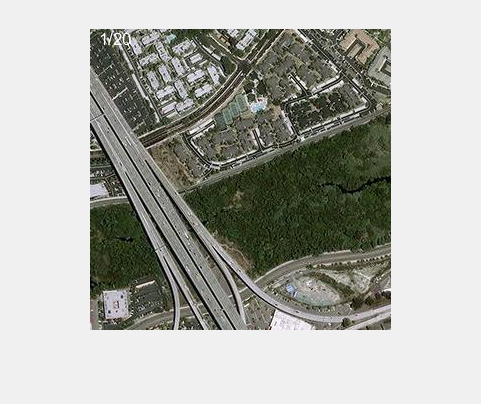

clc
clear all
close all

letter = "B";
directory = "Test Images/Snipped/"+letter+"/";
imagefiles = dir(directory);      
nfiles = length(imagefiles);    % Number of files found

% figure()
for ii=4:nfiles
   currentfilename = imagefiles(ii).name;
   currentimage = imread(directory+currentfilename);
   images{ii - 3} = currentimage;
   [~,imageNames{ii - 3},~] = fileparts(currentfilename);
   % subplot(nfiles-3, 1, ii - 3);
   % imshow(images{ii - 3});
end

% images{1} = imread("Test Images/Snipped/A/A4.jpg");
% images{2} = imread("Test Images/Snipped/A/A7.jpg");
% images{3} = imread("Test Images/Snipped/A/A15.jpg");
% images{4} = imread("Test Images/Snipped/A/A12.jpg");
% images{5} = imread("Test Images/Snipped/A/A18.jpg");

% images{1} = imread("leftoriginal.png")
% images{2} = imread("leftleft.png")

% % right = imread("leftshifted.png");
% figure()
% imshow(images{1})
% imshow(images{2})

fig = figure;
set(gcf,'Visible','on');

out = images{1};
thresh = 0.0006;
speedthresh = 0.01;
stitched = zeros(length(images),1);
stitched(1)=1;
length(images);

pltanim(out,stitched);

     1



    0.1374



     2



    0.1130



     3



    0.0124



     4



    0.2205



     5



    0.0378



     6



    0.2368



     7



    0.1835



     8



    0.2573



     9



    0.0238



    10



    0.0540



    11



    0.1932



    12



    0.0525



    13



    0.0051



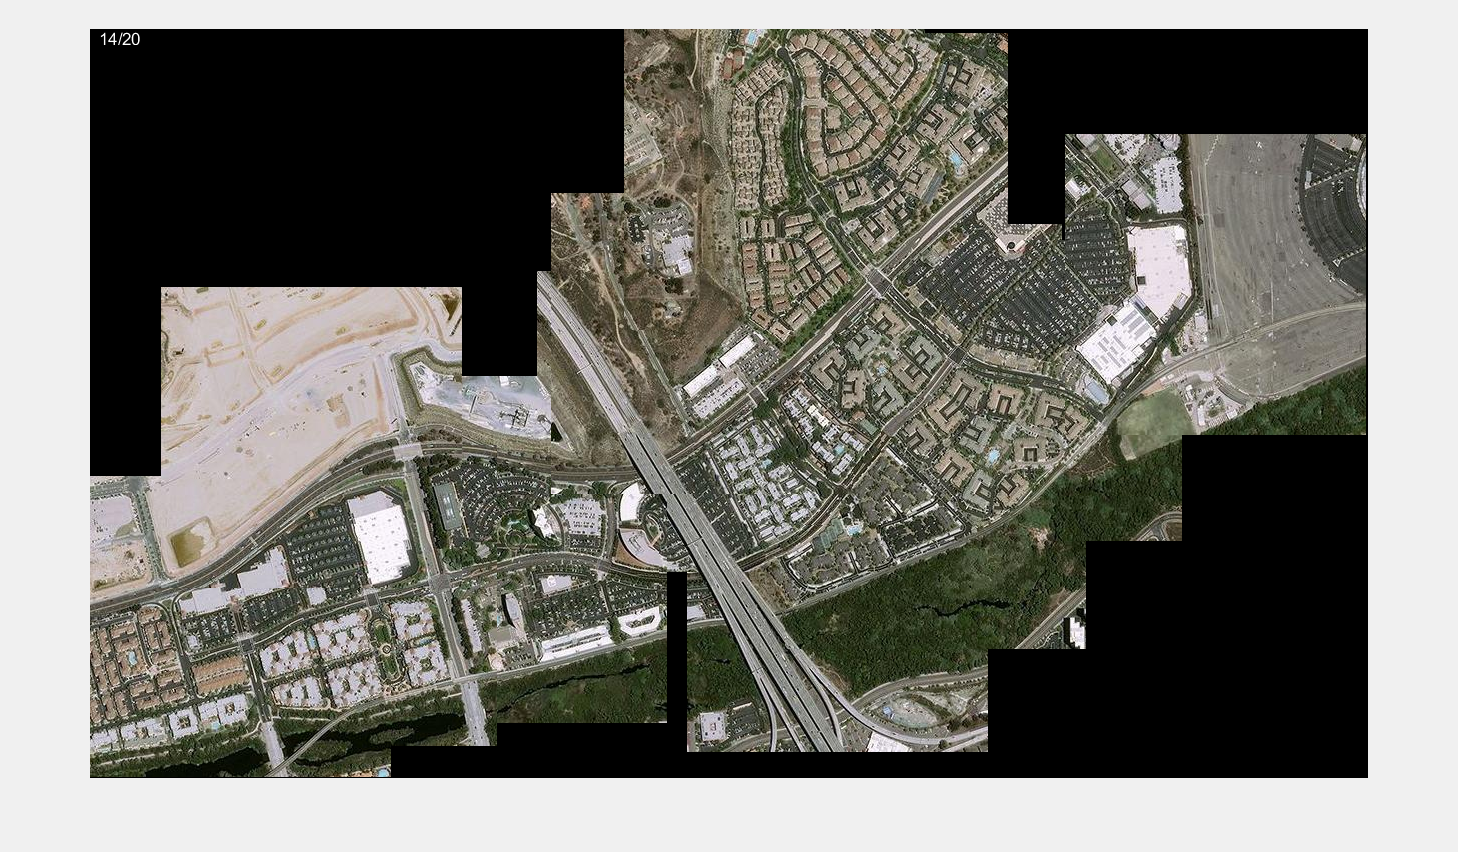

    14




for j=1:length(images)
    disp(j)
    confidences = zeros(length(images),3);
    for i=1:length(images)
        if stitched(i)==0
            [final_slope, final_length, final_delta_x, final_delta_y, final_confidence] = custom_sift(out, images{i}, 8, true);
            confidences(i,:)=[final_confidence,final_delta_x,final_delta_y];
            if confidences(i,1)>=speedthresh
                break
            end
        end
    end
    if sum(confidences(:,1)>=thresh)~=0
        [v,ind]=max(confidences(:,1));
        disp(v)
        stitched(ind)=1;
        out = merge_images(out, images{ind}, round(-confidences(ind,2)), round(-confidences(ind,3)));
        imwrite(out, "Output/"+letter+"/Run3_Stitch"+sum(stitched)+"_Conf"+round(v*10000)+".jpg");
        pltanim(out,stitched);
    else
        break
    end
end

sum(stitched)

ans = 14

imageNames(~stitched)

ans = 1×6 cell array
    {'B16'}    {'B20'}    {'B3'}    {'B4'}    {'B8'}    {'B9'}


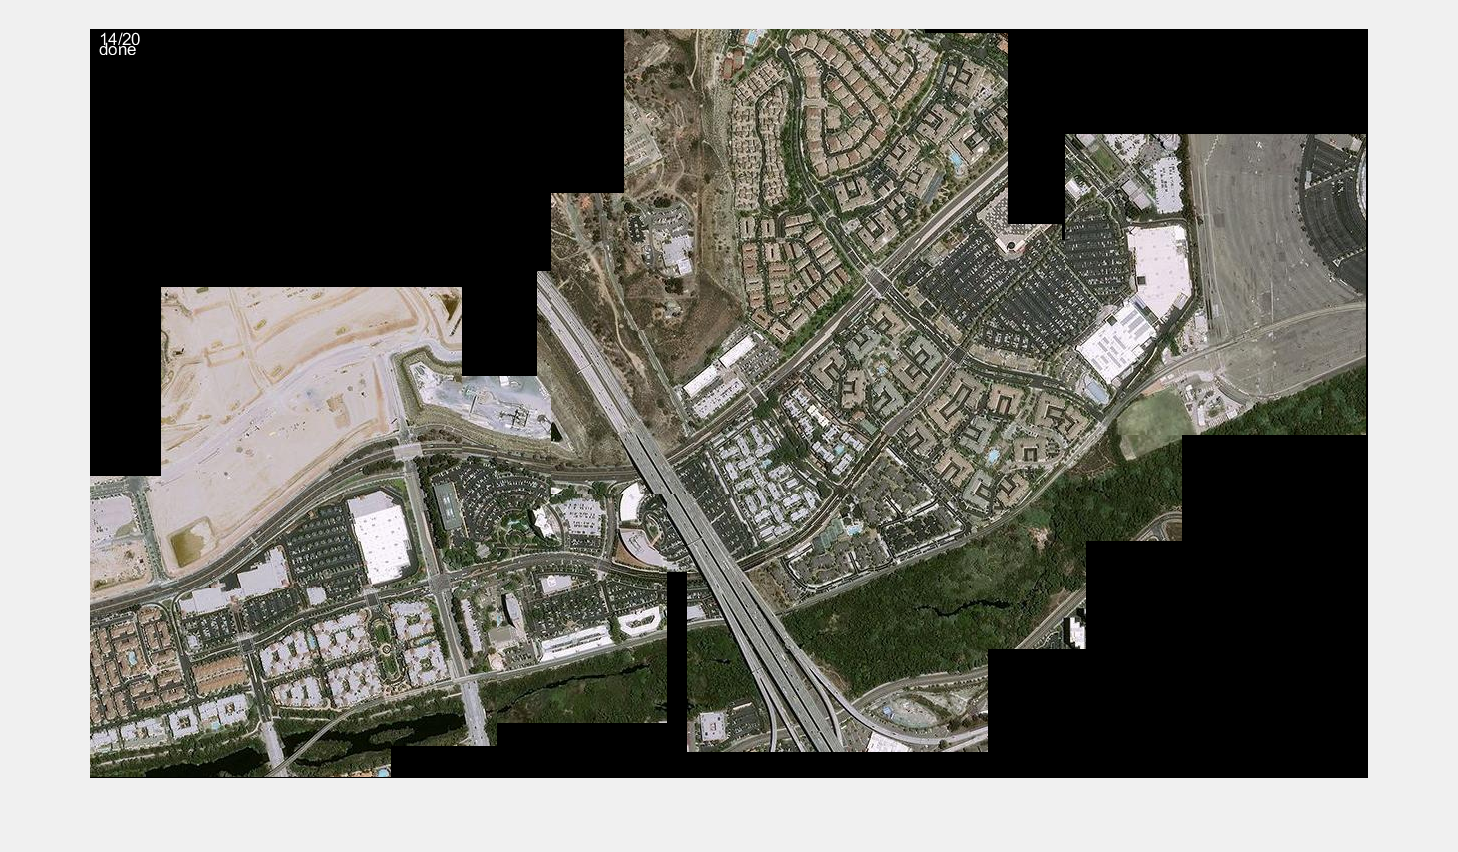

pltanim(out,stitched);
text(10,30,"Done!","Color",[1,1,1]);

function [] = pltanim(out, stitched)
        imshow(out);
        text(10,10,""+sum(stitched)+"/"+length(stitched),"Color",[1,1,1]);
        drawnow();
end